# Vehicle Tracking for Urban Air Mobility Using 5G Position Reference Signal

This example shows how to use 5G signals to track unmanned aerial vehicles (UAVs) for urban air mobility applications. This example considers that the ground stations are equipped with 5G devices to track the UAVs carrying 5G devices. You can simulate 5G signals in this environment and use them to estimate the time of arrival (TOA) of the signals at each UAV. Furthermore, you can use a multi-object tracking algorithm to process the TOA estimates to localize and track the UAVs. 

## Create Scenario

To create a UAV scenario, use the `createScenario` function. In this example, the UAV scenario consists of three UAVs and six base station gNodeBs (gNBs) on the top of buildings. In the figure below, the dotted lines represent the UAV trajectories and squares represent the buildings. The height of each gNB is selected to observe the heights of the UAVs with reasonable accuracy.

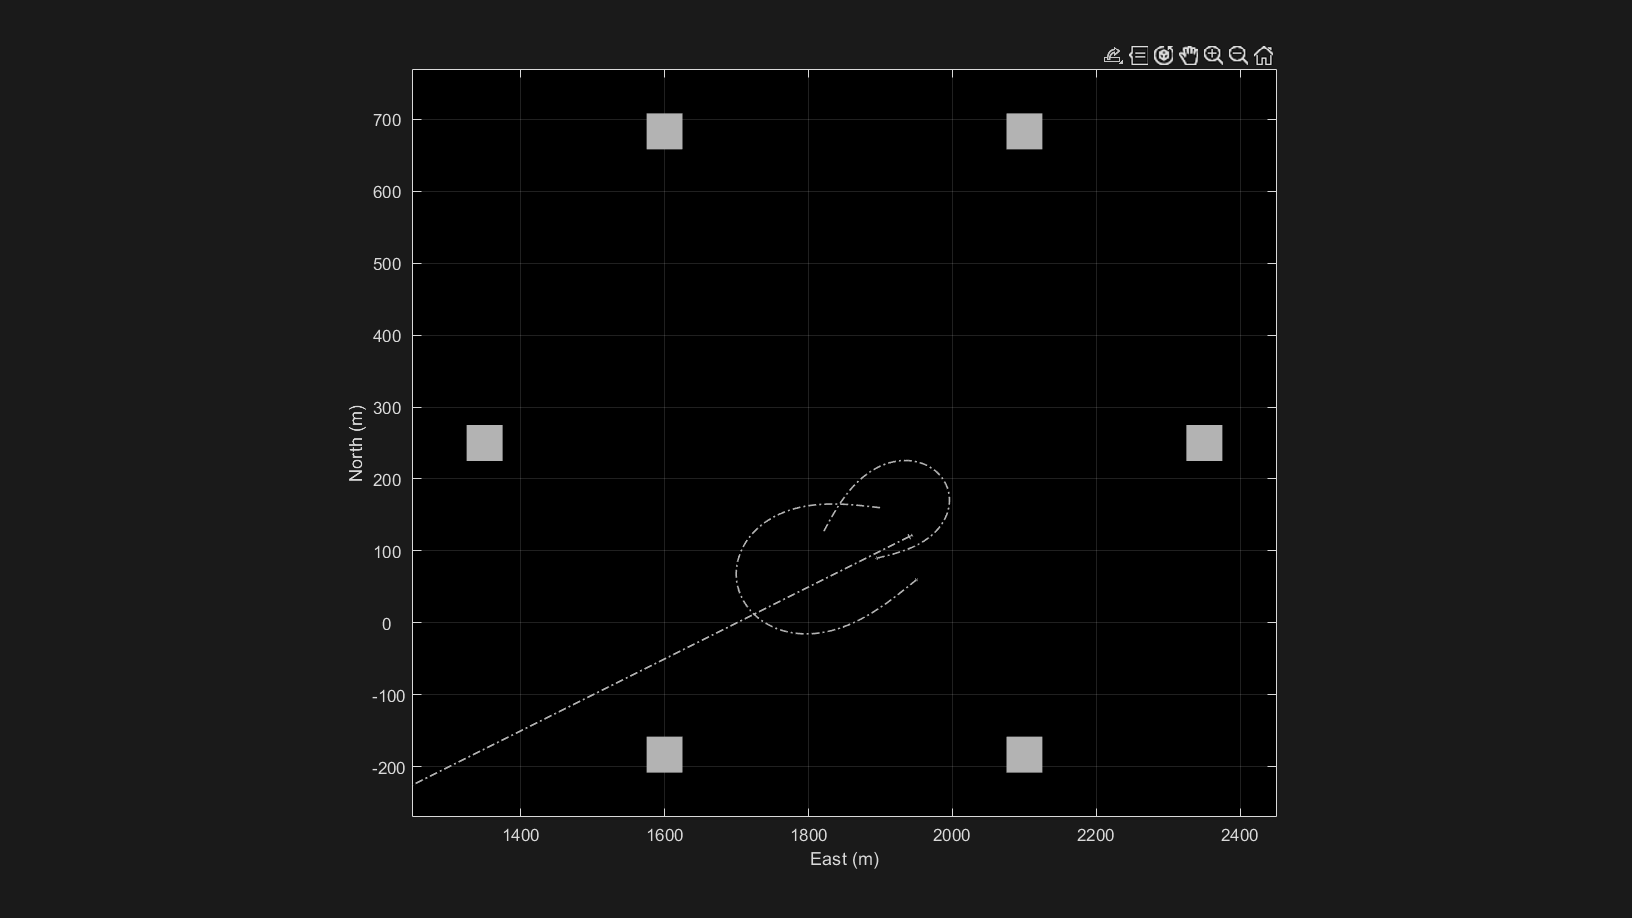

% Set RNG state for repeatability
rng(0);

% Create a UAV scenario
scene = createScenario();

% Create display
display = Helper5GTrackingExampleDisplay(ColorTheme="dark");

% Show scenario
plotScenario(display,scene)

## Configure 5G Carrier, PRS, and Path Loss

The figure shows one sample scenario with four gNBs and two UAVs. For UAV position estimation, consider one gNB as the reference gNB and other gNBs as neighboring gNBs. This example assumes that all the gNBs are operating at the same carrier frequency. As shown in the figure, each gNB transmits the positioning reference signal (PRS) waveforms for all the UAVs. This transmission happens in such a way that their allocation is not overlapped in time and frequency domain. Also, the PRS waveforms reach the UAVs at different time. This example further assumes that all the configured gNBs are available for the UAVs position estimation. The TOA values of the waveforms from each gNB are computed are used to estimate the position of each UAV using a tracker.

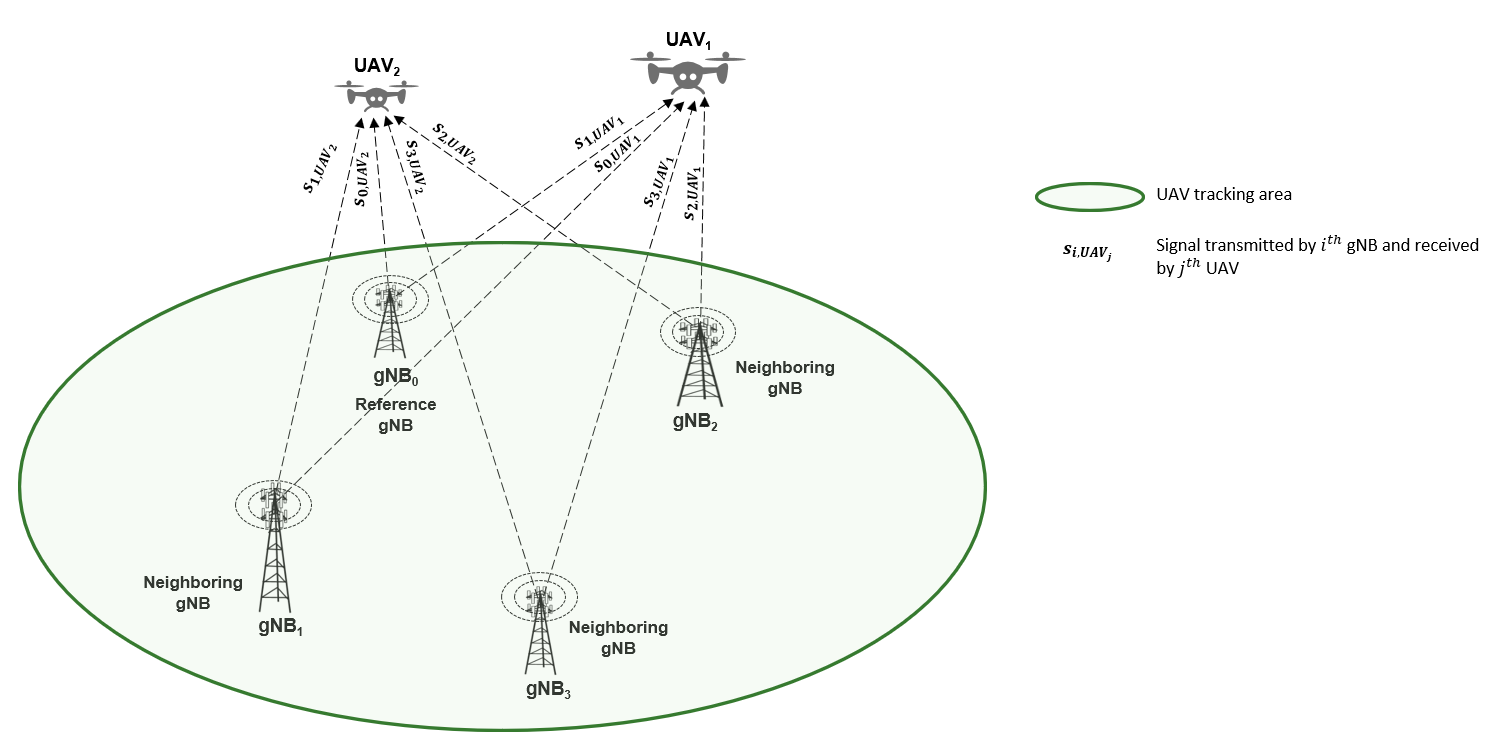

To create carriers and PRS resources with the given number of UAVs and gNBs, you use `getCarrierAndPRSConfigurations` function.

% Configure carrier and PRS resources
[uavTruth, gNBTruth] = getUAVAndGroundStationPoses(scene);
numgNBs = numel(gNBTruth);
numUAVs = numel(uavTruth);
[carrier,prs] = getCarrierAndPRSConfigurations(numgNBs,numUAVs);

% Validate that carriers are properly setup
validateCarriers(carrier);

% Compute the sample rate
ofdmInfo = nrOFDMInfo(carrier(1));
sampleRate = ofdmInfo.SampleRate;

% Set the carrier frequency (Hz)
fc = 3e9;

Configure the path loss for 5G signals using the [`nrPathLossConfig`](docid:5g_ref#mw_object_nrPathLossConfig) object.

% Path Loss Configuration
plCfg = nrPathLossConfig(Scenario="UMa");

## Create Tracker

You create a tracker using [trackerGNN](docid:fusion_ref#mw_53dbbb80-2a1c-4e68-a1f8-01be64767c6c) to process the TOA to estimate the position and velocity of each UAV. You use the technique described in the [Object Tracking Using Time Difference of Arrival](docid:fusion_ug#mw_b6e34a4d-fcb3-402b-8cdf-b20c718a8603) example for tracking multiple emitters with known identities.

% Create a tracker
tracker = trackerGNN(FilterInitializationFcn=@initUAVTrackingFilter);

You also set up performance metrics using [`trackErrorMetrics`](docid:fusion_ref#mw_2e1cf0e4-74bf-496b-ab37-afb35df6da02) to calculate the error between estimated and true positions of each UAV. You create two metric objects. The first metric measures the performance of instantenous or raw position estimates of the UAVs estimated using trilateration techniques. The second metric measures the performance of tracked position estimates using the tracker. 

% Tracked position error metric
trackedErrorMetricObj = trackErrorMetrics(ErrorFunctionFormat="custom",...
    EstimationErrorFcn=@trkError,...
    TrackIdentifierFcn=@(x)vertcat(x.ObjectClassID),...
    TruthIdentifierFcn=@(x)vertcat(x.ObjectID),...
    EstimationErrorLabels=["X", "Y", "Z"]);

% Instant error metric
instantErrorMetricObj = trackErrorMetrics(ErrorFunctionFormat="custom",...
    EstimationErrorFcn=@detError,...
    TrackIdentifierFcn=@(x)cellfun(@(d)d.ObjectClassID,x),...
    TruthIdentifierFcn=@(x)vertcat(x.ObjectID),...
    EstimationErrorLabels=["X", "Y", "Z"]);


## Simulate Scenario and Track UAVs

In this section, you advance the scenario to simulate the motion of UAVs and perform the following steps during each time instance.

- You simulate the transmitted and received 5G signals between ground stations and UAVs as shown in the 5G Signal Simulation subsection

- You estimate the TOA of each 5G signal at each UAV as shown in the TOA Estimation subsection

- You track UAVs using TOA as shown in the Tracking Using TOA Measurements subsection.

% Initialize variables for error calculation
n = ceil(scene.StopTime*scene.UpdateRate);
xErrorTracked = zeros(n,1);
yErrorTracked = zeros(n,1);
zErrorTracked = zeros(n,1);
xErrorInstant = zeros(n,1);
yErrorInstant = zeros(n,1);
zErrorInstant = zeros(n,1);
count = 1;

while advance(scene)
    % Current time
    time = scene.CurrentTime;

### 5G Signal Simulation

In this section, you use the simulated positions of UAVs and gNBs to simulate 5G signals transmitted by the gNBs and received by the UAVs. The supporting function `generateTxWaveform` generates the transmitted time-domain waveform.

    % Get the positions of UAVs and gNodeBs for 5G Simulation
    [uavTruth, gNBTruth] = getUAVAndGroundStationPoses(scene);
        
    % Get the gNB and UAV positions
    gNBPos = {gNBTruth.Position};
    UAVPos = {uavTruth.Position};    

    % Initialize with the slot number that corresponds to 'time'
    [carrier(:).NSlot] = deal(ceil(time/(1e-3*15/carrier(1).SubcarrierSpacing)));

    % Generate 5G time-domain waveform for the transmission from all the
    % gNBs
    [txWaveform,prsGrid] = generateTxWaveform(carrier,prs,numgNBs,numUAVs);

    % Check whether PRS is present in the current time instance or not. If
    % not, continue to the next time instance
    if all(cellfun(@sum,txWaveform) == 0)
        disp("PRS is not transmitted for this time instance. So advancing the scenario to next time instance.");
        continue;
    end    

 You can add path delays and path loss to simulate the received waveform at each UAV.

    % Apply line-of-sight path loss and path delays    
    rxWaveform = applyPathLossAndAddPathDelays(txWaveform,gNBPos,UAVPos,plCfg,fc,sampleRate);  

### TOA Estimation

In this section, you estimate the TOA of each PRS waveform from the gNBs to the UAVs. The supporting function `estimateTOAVals` uses the reference PRS to compute the time that the 5G signal takes to reach the UAV after transmission.

    % Estimate TOA values for each UAV and gNB pair in terms of nano seconds
    refGrid = prsGrid;
    toaInformation = estimateTOAVals(carrier,rxWaveform,refGrid,numUAVs,numgNBs);

### Tracking Using TOA Measurements

You use the TOA measurements to track each UAV. You first convert TOA measurements to time difference of arrival (TDOA) measurements. Then, you use a spherical intersection algorithm to estimate the  position of the UAV using the TDOA measurements. Next, you feed these position estimates to a multi-object tracker which uses these raw position estimates along with predictions of the UAV positions from past measurements to produce tracked position and velocity estimates of each UAV. For more details about each step, refer to the [Object Tracking Using Time Difference of Arrival](docid:fusion_ug#mw_b6e34a4d-fcb3-402b-8cdf-b20c718a8603) example.

    % Assemble toaInformation as objectDetection using gNB positions.
    toaDetections = assembleTOADetection(toaInformation, gNBTruth, time);

    % For the set of TOA detections from each UAV, compute the TDOA detections
    % using the difference between each TOA and the reference TOA (1st TOA)
    tdoaDetections = cell(numel(toaDetections),1);
    for i = 1:numel(toaDetections)
        tdoaDetections{i} = convertTOA2TDOADetections(toaDetections{i});
    end

    % For each TDOA set of detections from a unique UAV, compute
    % position detections using spherical intersection algorithm.
    positionDetections = cell(numel(tdoaDetections),1);
    for i = 1:numel(tdoaDetections)
        positionDetections{i} = convertTDOA2Pos(tdoaDetections{i},true);
    end

    % Track UAVs by feeding their position estimates to a tracker
    tracks = tracker(positionDetections, time);

    % Calculate the error in raw position estimates
    detIDs = cellfun(@(x)x.ObjectClassID,positionDetections);
    [xErrorInstant(count),yErrorInstant(count),zErrorInstant(count)] = instantErrorMetricObj(positionDetections, detIDs, uavTruth, detIDs); %#ok<*SAGROW>

    % Calculate the error in tracked position estimates
    trkIDs = vertcat(tracks.ObjectClassID);
    [xErrorTracked(count),yErrorTracked(count),zErrorTracked(count)] = trackedErrorMetricObj(tracks, trkIDs, uavTruth, trkIDs);

Update the display to visualize the scene, TDOA detections, estimated positions from TDOA, and the tracked positions. 

    % Update plots
    display(scene, tdoaDetections, positionDetections, tracks);

    % counter

Invalid or deleted object.

Error in Helper5GTrackingDisplayComponent/stepImpl (line 219)
                display.Axes.XLim = uavMotion(1) + [-10 10];

Error in Helper5GTrackingExampleDispl

    count = count + 1;
end

From the image above, notice that all UAVs were tracked and their position estimates were close to the true position of the UAVs.

## Tracking Accuracy Analysis

To quantitatively understand the errors, plot the average estimated error in X-, Y-, and Z-directions for both tracked and instantaneous position estimates. Notice that the error in tracked position estimates are below 2.5 meters for each direction. Also, the tracker is able to reduce and smooth the error in the raw positions in each direction. 

figure(Visible="on",Units="normalized",Position=[0.1 0.1 0.8 0.8]);

% Plot X error
ax = subplot(3,1,1);
plot(ax,xErrorInstant,LineWidth=1);
hold on
plot(ax,xErrorTracked,LineWidth=1);
xlabel("Time step");
ylabel("X Error (m)");
grid(ax,"on");
legend(["Raw","Tracked"],Location="bestoutside");

% Plot Y error
ax = subplot(3,1,2);
plot(ax,yErrorInstant,LineWidth=1);
hold on
plot(ax,yErrorTracked,LineWidth=1);
xlabel("Time step");
ylabel("Y Error (m)");
grid(ax,"on");
legend(["Raw","Tracked"],Location="bestoutside");

% Plot Z error
ax = subplot(3,1,3);
plot(ax,zErrorInstant,LineWidth=1);
hold on
plot(ax,zErrorTracked,LineWidth=1);
xlabel("Time step");
ylabel("Z Error (m)");
grid(ax,"on");
legend(["Raw","Tracked"],Location="bestoutside");

## Summary

This example shows how to simulate 5G signals in a UAV scenario and how to process them using a tracker to estimate the position and velocity of each UAV. This example also shows how a tracker can produce more accurate position estimates of the UAVs compared to the raw estimates obtained by just using TOA measurements at each time step.

## Supporting Functions

function scene = createScenario()
    % scene = createScenario() creates the uavScenario object with three UAVs
    % and six base stations.

    minHeight = 1.6925e+03;
    latlonCenter = [39.9786 -105.2882 minHeight];
    
    % Set the update rate as integer multiples of 1 ms, so that it
    % corresponds to the start of a slot when the instantaneous time is converted to
    % slot number in the 5G processing
    scene = uavScenario(UpdateRate=10,...
        StopTime=50,...
        ReferenceLocation=latlonCenter,...
        MaxNumFrames=200,...
        HistoryBufferSize=1000);
    
    % Package delivery drone
    waypointsA = [1895 90 20; 1995 180 35; 1820 125 20];
    timeA = [0 25 50];
    trajA = waypointTrajectory(waypointsA, TimeOfArrival=timeA,...
        ReferenceFrame="ENU",...
        AutoBank=true);

    uavA = uavPlatform("UAV1", scene, ...
        Trajectory=trajA,...
        ReferenceFrame="ENU");
    updateMesh(uavA, "quadrotor", {5}, 0*[1 1 1], eye(4));
    
    % Air Taxi
    waypointsB = [1940 120 50; 1240 -230 50];
    timeB = [0 50];
    trajB = waypointTrajectory(waypointsB, TimeOfArrival=timeB,...
        ReferenceFrame="ENU",...
        AutoBank=true);
    uavB = uavPlatform("UAV2", scene, ...
        Trajectory=trajB,...
        ReferenceFrame="ENU");
    updateMesh(uavB, "fixedwing", {10},  0*[1 1 1], eye(4));
    
    % Grid line maintenance 
    waypointsC = [1950 60 35; 1700 60 35; 1900 160 35];
    timeC = linspace(0,50,size(waypointsC,1));
    trajC = waypointTrajectory(waypointsC, TimeOfArrival=timeC,...
        ReferenceFrame="ENU",...
        AutoBank=true);
    uavC = uavPlatform("UAV3", scene, ...
        Trajectory=trajC,...
        ReferenceFrame="ENU");
    updateMesh(uavC, "quadrotor", {5}, 0*[1 1 1], eye(4));
    
    % Add six 5G ground stations in a circular region
    xC = [1850;250;0];
    r = 500;
    n = 6;
    dT = 360/n;
    theta = dT:dT:360;
    z = [50 75 100 240 10 50];
    pos = xC + [r.*cosd(theta);r.*sind(theta);z];
    for i = 1:size(pos,2)
        gs = uavPlatform(strcat("GS",num2str(i)),...
            scene,ReferenceFrame="ENU",...
            InitialPosition=pos(:,i)');
        updateMesh(gs,"cuboid",{[50,50,pos(3,i)]},0.3*[1 1 1],[0 0 -pos(3,i)/2],[1 0 0 0]);
    end
    
    % Set up the scene
    setup(scene);
end

function [ueTruth, gNBTruth] = getUAVAndGroundStationPoses(scene)
    % [ueTruth, gNBTruth] = getUAVAndGroundStationPoses(scene) returns
    % the gNB and UAV pose structures.

    poses = struct("Identity",{},"Position",{},"Velocity",{},"ObjectID",{});
    isValid = false(1,numel(scene.Platforms));
    % Assemble poses
    for i = 1:numel(scene.Platforms)
        uavMotion = read(scene.Platforms(i));
        poses(i).Identity = scene.Platforms(i).Name;
        poses(i).Position = uavMotion(1:3);
        poses(i).Velocity = uavMotion(4:6);
        poses(i).ObjectID = i;
        isValid(i) = all(~isnan(uavMotion));
    end
    poses = poses(isValid);
    
    % Separate into uePoses and gNBPoses
    isUAV = arrayfun(@(x)startsWith(x.Identity,'UAV'),poses,UniformOutput=true);
    ueTruth = poses(isUAV);
    gNBTruth = poses(~isUAV);
end

function toaDetections = assembleTOADetection(toaInformation, gNodeBTruth, time)
    % toaDetections = assembleTOADetection(toaInformation, gNodeBTruth, time)
    % assembles the TOA information in an object of type objectDetection.

    toaNoise = 265;
    numUAVs = numel(toaInformation);
    numgNBs = numel(gNodeBTruth);
    toaDetections = cell(numUAVs,1);
    
    % For each UAV
    for i = 1:numUAVs
        % For each TOA reported by UAV, convert it to objectDetection
        % format.
        toaForThisUAV = cell(numgNBs,1);
        for j = 1:numgNBs
            % Position of gNodeB 
            gNodeBPos = gNodeBTruth(j).Position;

            % Assemble
            toaObjectDetection = objectDetection(time, toaInformation(i).TOAEstimate(j),MeasurementNoise=toaNoise,...
                ObjectClassID=toaInformation(i).ID,...
                MeasurementParameters=struct(OriginPosition=gNodeBPos));

            % Concatenate for each UAV
            toaForThisUAV{j} = toaObjectDetection;
        end
        toaDetections{i} = toaForThisUAV;
    end
end

function varargout = convertTDOA2Pos(tdoaDets, reportDetection)
    % varargout = convertTDOA2Pos(tdoaDets, reportDetection) uses the
    % spherical intersection algorithm to find the object position from the
    % TDOA detections of the same object.    
    %
    % This function assumes that all TDOAs are measured with respect to the
    % same reference sensor. 
    %
    % [pos, posCov] = convertTDOA2Pos(tdoaDets) returns the estimated position
    % and position uncertainty covariance.
    %
    % posDetection = convertTDOA2Pos(tdoaDets, true) returns the estimate
    % position and uncertainty covariance as an objectDetection object. 
    
    if nargin < 2
        reportDetection = false;
    end
    
    % Collect scaling information
    params = helperGetEmissionSpeedAndTimeScale;
    emissionSpeed = params.EmissionSpeed;
    timeScale = params.TimeScale;
    
    % Location of the reference receiver
    referenceLoc = tdoaDets{1}.MeasurementParameters(2).OriginPosition(:); 
    
    % MeasurementParameters include the info about the gNBs position. First
    % elemet is the neighboring gNB position and second element is the
    % reference gNB position.
    
    % Formulate the problem. See the linked example for TDOA tracking for more details
    d = zeros(numel(tdoaDets),1);
    delta = zeros(numel(tdoaDets),1);
    S = zeros(numel(tdoaDets),3);
    for i = 1:numel(tdoaDets)
        receiverLoc = tdoaDets{i}.MeasurementParameters(1).OriginPosition(:);
        d(i) = tdoaDets{i}.Measurement*emissionSpeed/timeScale;
        delta(i) = norm(receiverLoc - referenceLoc)^2 - d(i)^2;
        S(i,:) = receiverLoc - referenceLoc;
    end
    
    % Pseudo-inverse of S
    Swstar = pinv(S);
    
    % Assemble the quadratic range equation
    STS = (Swstar'*Swstar);
    a = 4 - 4*d'*STS*d;
    b = 4*d'*STS*delta;
    c = -delta'*STS*delta;
    
    Rs = zeros(2,1);
    % Imaginary solution, return a location outside coverage
    if b^2 < 4*a*c 
        pos = 1e10*ones(3,1);
        posCov = 1e10*eye(3);
    else
        % Two range values
        Rs(1) = (-b + sqrt(b^2 - 4*a*c))/(2*a);
        Rs(2) = (-b - sqrt(b^2 - 4*a*c))/(2*a);
        
        % If one is negative, use the positive solution
        if prod(Rs) < 0
            Rs = Rs(Rs > 0);
            pos = 1/2*Swstar*(delta - 2*Rs(1)*d) + referenceLoc;
        else % Use range which minimize the error
            xs1 = 1/2*Swstar*(delta - 2*Rs(1)*d);
            xs2 = 1/2*Swstar*(delta - 2*Rs(2)*d);
            e1 = norm(delta - 2*Rs(1)*d - 2*S*xs1);
            e2 = norm(delta - 2*Rs(2)*d - 2*S*xs2);
            if e1  > e2
                pos = xs2 + referenceLoc;
            else
                pos = xs1 + referenceLoc;
            end
        end
    end
    
    % If required, compute the uncertainty in the position
    if nargout > 1 || reportDetection
        posCov = calculatePositionCovariance(pos,tdoaDets,timeScale,emissionSpeed);
    end
    
    if reportDetection
        varargout{1} = objectDetection(tdoaDets{1}.Time,pos,MeasurementNoise=posCov,ObjectClassID=tdoaDets{1}.ObjectClassID);
    else
        varargout{1} = pos;
        if nargout > 1
            varargout{2} = posCov;
        end
    end

end

function measCov = calculatePositionCovariance(pos,thisDetections,timeScale,emissionSpeed)
    % measCov = calculatePositionCovariance(pos,thisDetections,timeScale,emissionSpeed)
    % measures the position covariance.

    n = numel(thisDetections);
    % Complete Jacobian from position to N TDOAs
    H = zeros(n,3);
    % Covariance of all TDOAs
    S = zeros(n,n);
    for i = 1:n
       e1 = pos - thisDetections{i}.MeasurementParameters(1).OriginPosition(:);
       e2 = pos - thisDetections{i}.MeasurementParameters(2).OriginPosition(:);
       Htdoar1 = (e1'/norm(e1))*timeScale/emissionSpeed;
       Htdoar2 = (e2'/norm(e2))*timeScale/emissionSpeed;
       H(i,:) = Htdoar1 - Htdoar2;
       S(i,i) = thisDetections{i}.MeasurementNoise;
    end
    Pinv = H'/S*H;
    % Z is not measured, use 1 as the covariance
    if Pinv(3,3) < eps
        Pinv(3,3) = 1;
    end
    
    % Insufficient information in TDOA
    if rank(Pinv) >= 3
        measCov = eye(3)/Pinv;
    else
        measCov = inf(3);
    end
    
    % Replace inf with large number
    measCov(~isfinite(measCov)) = 100;
    
    % Return a true symmetric, positive definite matrix for covariance.
    measCov = (measCov + measCov')/2;
end

function [tdoaDetections, isValid] = convertTOA2TDOADetections(toaDetections)
    % This function converts multiple TOA detections from the same object to
    % TDOA detections assuming 1 reference sensor. This allows it to directly
    % use spherical intersection algorithm. 
    
    sampleTDOADetection = objectDetection(toaDetections{1}.Time,toaDetections{1}.Measurement,...
        MeasurementParameters=repmat(toaDetections{1}.MeasurementParameters,2,1));
    
    % Number of TOA detections
    n = numel(toaDetections);
    
    % At least 2 detections must be used for TDOA calculation
    assert(n > 1, "At least 2 TOA Detections required to form a TDOA");
    
    % Allocate memory for TDOA detection
    tdoaDetections = repmat({sampleTDOADetection},n-1,1);
    
    % Position of the reference receiver (first TOA in the list)
    referenceParams = toaDetections{1}.MeasurementParameters;
    referencePos = referenceParams.OriginPosition;
    
    % A pair of TOA may combine to form an invalid TDOA because its greater
    % than the inter distance between receivers. 
    isValid = false(1,n-1);
    
    % Get emission speed and time scale
    globalParams = helperGetEmissionSpeedAndTimeScale();
    emissionSpeed = globalParams.EmissionSpeed;
    timeScale = globalParams.TimeScale;
    
    % Fill TDOA detections
    for i = 2:numel(toaDetections)
        % Position of receiver
        receiverPos = toaDetections{i}.MeasurementParameters.OriginPosition;
    
        % TDOA = TOA - TOAreference
        tdoaDetections{i-1}.Measurement = toaDetections{i}.Measurement - toaDetections{1}.Measurement; % TDOA
    
        % Noise additions
        tdoaDetections{i-1}.MeasurementNoise = toaDetections{i}.MeasurementNoise + toaDetections{1}.MeasurementNoise;
    
        % Use SensorIndex of the non-reference receiver
        tdoaDetections{i-1}.SensorIndex = toaDetections{i}.SensorIndex;
    
        % Fill MeasurementParameters
        tdoaDetections{i-1}.MeasurementParameters(1) = toaDetections{i}.MeasurementParameters;
        tdoaDetections{i-1}.MeasurementParameters(2) = referenceParams;
    
        % Check if a TDOA is valid
        isValid(i-1) = norm(receiverPos - referencePos)/emissionSpeed*timeScale > abs(tdoaDetections{i-1}.Measurement);

        tdoaDetections{i-1}.ObjectClassID = toaDetections{1}.ObjectClassID;
    end
end

function [txWaveform,prsGrid] = generateTxWaveform(carrier,prs,numgNBs,numUAVs)
    % [txWaveform,prsGrid] = generateTxWaveform(carrier,prs,numgNBs,numUAVs)
    % generates the transmit waveforms from all the gNBs along with the PRS
    % grids for each gNB and UAV pair. 
    
    % These PRS grids are going to be used as reference grids during
    % receiver side processing instead of regenerating them again.
   
    % Generate PRS Resources        
    prsGrid = cell(numUAVs,numgNBs);
    [prsSym,prsInd] = deal(cell(numUAVs,numgNBs));
    for ueNum = 1:numUAVs
        for gNBIdx = 1:numgNBs
            % Create an empty resource grid spanning one slot in time domain
            slotGrid = nrResourceGrid(carrier(gNBIdx),1);

            % Generate PRS symbols and indices
            prsSym{ueNum,gNBIdx} = nrPRS(carrier(gNBIdx),prs(ueNum,gNBIdx));
            prsInd{ueNum,gNBIdx} = nrPRSIndices(carrier(gNBIdx),prs(ueNum,gNBIdx));

            % Map PRS resources to slot grid
            slotGrid(prsInd{ueNum,gNBIdx}) = prsSym{ueNum,gNBIdx};
            prsGrid{ueNum,gNBIdx} = [prsGrid{ueNum,gNBIdx} slotGrid];
        end
    end

    % Perform OFDM modulation of PRS and data signal at each gNB
    txWaveform = cell(1,numgNBs);
    for waveIdx = 1:numgNBs
        carrier(waveIdx).NSlot = 0;
        allUAVsGrid = zeros(size(prsGrid{1,1}));
        for ueNum = 1:numUAVs
            allUAVsGrid = allUAVsGrid + prsGrid{ueNum,waveIdx};
        end
        txWaveform{waveIdx} = nrOFDMModulate(carrier(waveIdx),allUAVsGrid);
    end
end

function [carrier,prs] = getCarrierAndPRSConfigurations(numgNBs,numUAVs)
    % [carrier,prs] = getCarrierAndPRSConfigurations(numgNBs,numUAVs)
    % configures the carriers for all the gNBs and PRS configurations for
    % each gNB and UAV pair.

    cellIds = randperm(1008,numgNBs) - 1;
    
    % Configure carrier properties
    carrier = repmat(nrCarrierConfig,1,numgNBs);    
    for gNBIdx = 1:numgNBs
        carrier(gNBIdx).NCellID = cellIds(gNBIdx);
        carrier(gNBIdx).NSizeGrid = 275;
    end    
    
    % PRS Configuration
    prsIDs = reshape(randperm(4096,numgNBs*numUAVs) - 1,numUAVs,numgNBs);
    
    % Configure PRS properties
    prs = nrPRSConfig;
    prs.PRSResourceSetPeriod = 'on';
    prs.PRSResourceOffset = 0;
    prs.PRSResourceRepetition = 1;
    prs.PRSResourceTimeGap = 1;
    prs.MutingPattern1 = [];
    prs.MutingPattern2 = [];
    prs.NumRB = carrier(1).NSizeGrid;
    prs.RBOffset = carrier(1).NStartGrid;
    prs.CombSize = 6;
    prs.NumPRSSymbols = 12;
    prs.SymbolStart = 0;
    prs.REOffset = 0;
    prs = repmat(prs,numUAVs,numgNBs);
    for ueNum = 1:numUAVs
        % Consider different RE offsets to avoid the overlapping
        [prs(ueNum,:).REOffset] = deal(2*(ueNum-1));
        for gNBIdx = 1:numgNBs
            prs(ueNum,gNBIdx).NPRSID = prsIDs(ueNum,gNBIdx);
        end
    end
end

function validateCarriers(carrier)
    %   validateCarriers(CARRIER) validates the carrier properties of all
    %   gNBs.

    % Validate physical layer cell identities
    cellIDs = [carrier(:).NCellID];
    if numel(cellIDs) ~= numel(unique(cellIDs))
        error("nr5g:invalidNCellID","Physical layer cell identities of all of the carriers must be unique.");
    end
    
    % Validate subcarrier spacings
    scsVals = [carrier(:).SubcarrierSpacing];
    if ~isscalar(unique(scsVals))
        error("nr5g:invalidSCS","Subcarrier spacing values of all of the carriers must be same.");
    end
    
    % Validate cyclic prefix lengths
    cpVals = {carrier(:).CyclicPrefix};
    if ~all(strcmpi(cpVals{1},cpVals))
        error("nr5g:invalidCP","Cyclic prefix lengths of all of the carriers must be same.");
    end
    
    % Validate NSizeGrid values
    nSizeGridVals = [carrier(:).NSizeGrid];
    if ~isscalar(unique(nSizeGridVals))
        error("nr5g:invalidNSizeGrid","NSizeGrid of all of the carriers must be same.");
    end
    
    % Validate NStartGrid values
    nStartGridVals = [carrier(:).NStartGrid];
    if ~isscalar(unique(nStartGridVals))
        error("nr5g:invalidNStartGrid","NStartGrid of all of the carriers must be same.");
    end

end

function [rxWaveform, pathDelays] = applyPathLossAndAddPathDelays(txWaveform,gNBPos,UAVPos,plCfg,fc,sampleRate)
    % [rxWaveform, pathDelays] = applyPathLossAndAddPathDelays(txWaveform,gNBPos,UAVPos,plCfg,fc,sampleRate)
    % models the received signal at each UAV by delaying each gNB
    % transmission according to the physical distance between gNB and UAV
    % and by attenuating the received signal from each gNB. This function
    % ensures that all the waveforms at UAV side are of the same length, by
    % padding the received waveform from each gNB with relevant number of
    % zeros.
    
    % Get the number of UAVs and gNBs
    numUAVs = numel(UAVPos);
    numgNBs = numel(gNBPos);

    % Compute the path delays in terms of number of samples   
    speedOfLight = physconst("LightSpeed"); % Speed of light in m/s
    pathDelays = zeros(numUAVs,numgNBs);
    radius = cell(numUAVs,numgNBs);
    for ueNum = 1:numUAVs
        UAVPosition = UAVPos{ueNum};
        for gNBIdx = 1:numgNBs
            radius{ueNum,gNBIdx} = rangeangle(gNBPos{gNBIdx}',UAVPosition');
            delay = radius{ueNum,gNBIdx}/speedOfLight;            % Delay in seconds
            pathDelays(ueNum,gNBIdx) = round(delay*sampleRate);   % Delay in samples
        end
    end

    % Initialize the received waveform
    rxWaveform = repmat({zeros(length(txWaveform{1}) + max(pathDelays(:)),1)},1,numUAVs);
    rx = cell(numUAVs,numgNBs);

    % Add path delays and apply path loss
    los = true*(ones(1,numgNBs));
    for ueNum = 1:numUAVs
        UAVPosition = UAVPos{ueNum};
        for gNBIdx = 1:numgNBs
            % Calculate path loss for each gNB and UAV pair
            PLdB = nrPathLoss(plCfg,fc,los(gNBIdx),[gNBPos{gNBIdx}(:)],[UAVPosition(:)]);
            if PLdB < 0 || isnan(PLdB) || isinf(PLdB)
                error("nr5g:invalidPL","Computed path loss (" + num2str(PLdB) + ...
                    ") is invalid. Try changing the UAV or gNB positions, or path loss configuration.");
            end
            PL = 10^(PLdB/10);

            % Add delay, pad, and attenuate
            rx{ueNum,gNBIdx} = [zeros(pathDelays(ueNum,gNBIdx),1); txWaveform{1,gNBIdx}; ...
                zeros(max(pathDelays(:))-pathDelays(ueNum,gNBIdx),1)]/sqrt(PL);

            % Sum waveforms from all gNBs
            rxWaveform{ueNum} = rxWaveform{ueNum} + rx{ueNum,gNBIdx};
        end
    end
end

function toaInformation = estimateTOAVals(carrier,rxWaveform,prsGrid,numUAVs,numgNBs)
    % toaInformation = estimateTOAVals(carrier,rxWaveform,prsGrid,numUAVs,numgNBs)
    % estimates the TOAs by performing the correlation on the incoming
    % signal at each UAV with reference PRS generated by each gNB. This
    % function returns the TOA information in terms of nano seconds.

    % Get the OFDM modulation related information
    ofdmInfo = nrOFDMInfo(carrier(1));

    % Compute the TOAs
    toaInformation = struct(ID={},TOAEstimate={});
    for ueNum = 1:numUAVs
        for gNBIdx = 1:numgNBs
            [~,mag] = nrTimingEstimate(carrier(gNBIdx),rxWaveform{ueNum},prsGrid{ueNum,gNBIdx});
            % Extract correlation data samples spanning about 1/14 ms for normal
            % cyclic prefix and about 1/12 ms for extended cyclic prefix (this
            % truncation is to ignore noisy side lobe peaks in correlation outcome)
            corr = mag(1:(ofdmInfo.Nfft*carrier(1).SubcarrierSpacing/15));
            % Delay estimate is at point of maximum correlation
            maxCorr = max(corr);
            toaInformation(ueNum).TOAEstimate(gNBIdx) = (find(corr == maxCorr,1)-1)*1e9/ofdmInfo.SampleRate;
            toaInformation(ueNum).ID = ueNum;
        end
    end
end

function [xError, yError, zError] = trkError(track, truth)
    % [xError, yError, zError] = trkError(track, truth) computes the errors
    % between track and truth
    trkPos = track.State(1:2:end);
    truthPos = truth.Position;
    xError = (truthPos(1) - trkPos(1));
    yError = (truthPos(2) - trkPos(2));
    zError = (truthPos(3) - trkPos(3));
end

function [xError, yError, zError] = detError(detection, truth)
    % [xError, yError, zError] = detError(detection, truth) computes the
    % errors between detection and truth
    detPos = detection{1}.Measurement;
    truthPos = truth.Position;
    xError = (truthPos(1) - detPos(1));
    yError = (truthPos(2) - detPos(2));
    zError = (truthPos(3) - detPos(3));
end
    
function filter = initUAVTrackingFilter(detection)
    % filter = initUAVTrackingFilter(detection) initializes a filter for
    % tracking. Increase process noise to allow maneuvers.
    filter = initcvekf(detection);
    filter.ProcessNoise = 4*eye(3);
end